Problem 1

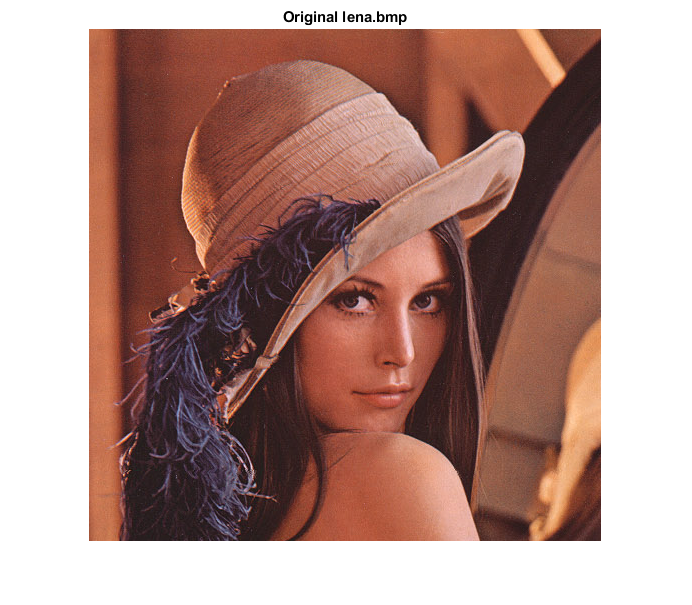

rgb = imread('lena.bmp');
figure;
imshow(rgb);
title('Original lena.bmp')

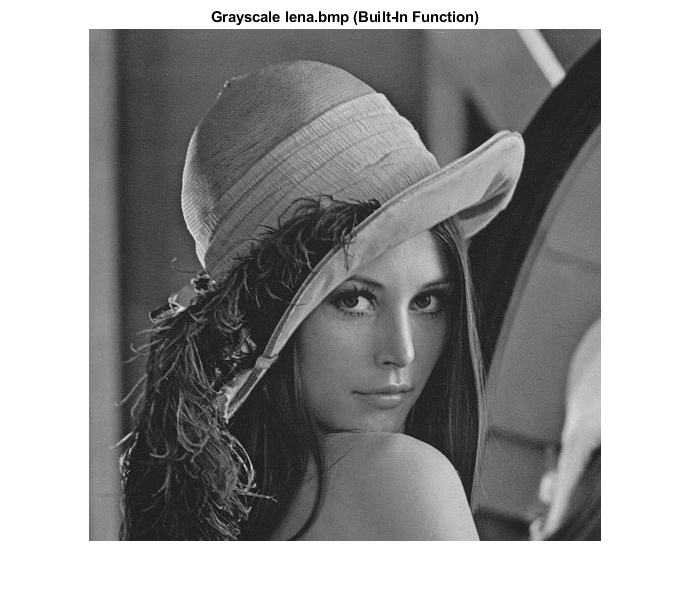


gray = rgb2gray(rgb);
figure;
imshow(gray)
title('Grayscale lena.bmp (Built-In Function)')

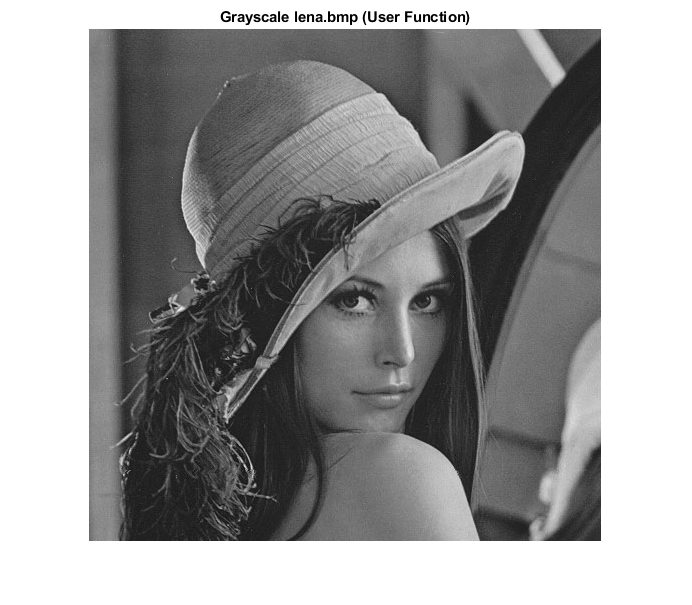


my_gray = grayscale_intensity(rgb);
figure;
imshow(my_gray)
title('Grayscale lena.bmp (User Function)')


figure;
imwrite(my_gray, 'lena_gray.jpg')

Problem 2

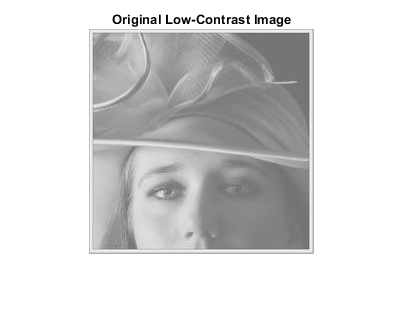

img = imread('lowcontrast.jpg');
figure;
imshow(img)
title('Original Low-Contrast Image')

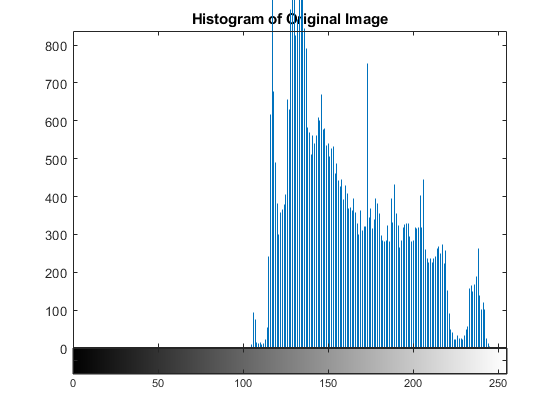


figure;
imhist(img)
title('Histogram of Original Image')

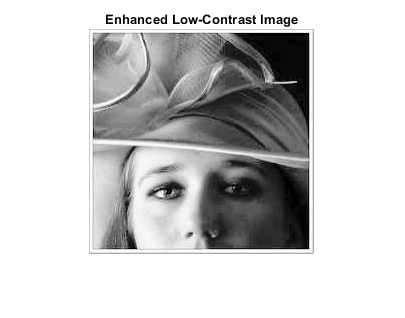


newcmap = histeq(img);

figure;
imshow(newcmap)
title('Enhanced Low-Contrast Image')

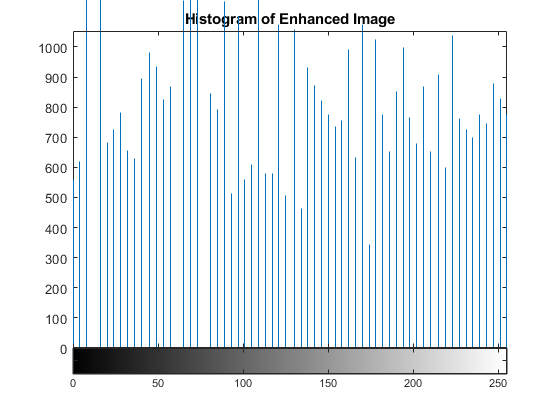


figure;
imhist(newcmap)
title('Histogram of Enhanced Image')

Problem 3

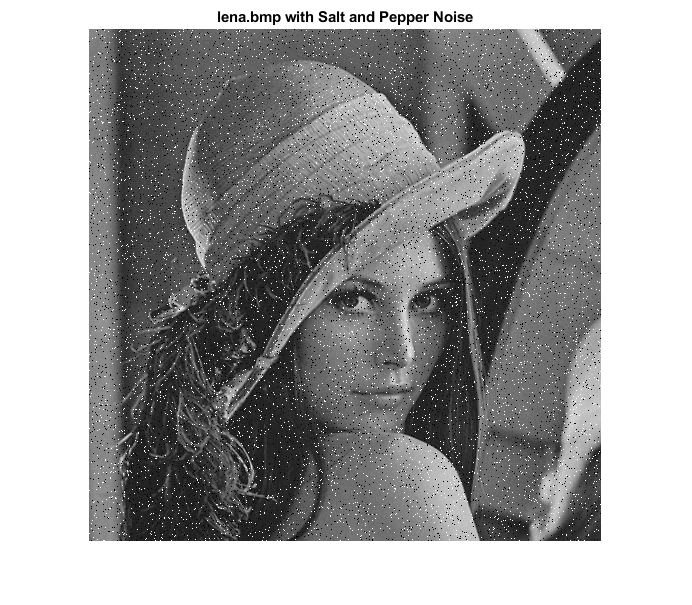

noisy_lena = imnoise(gray, 'salt & pepper', 0.05);

figure;
imshow(noisy_lena)
title('lena.bmp with Salt and Pepper Noise')

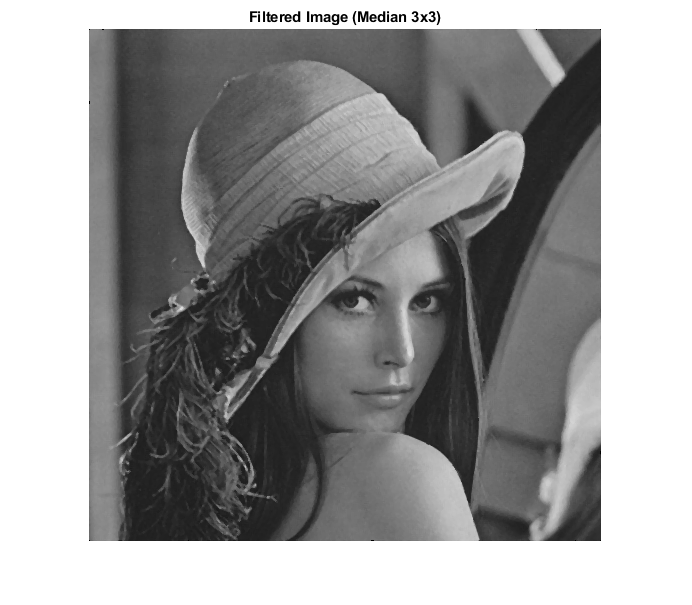


filtered_3x3 = medfilt2(noisy_lena, [3 3]);

figure;
imshow(filtered_3x3)
title('Filtered Image (Median 3x3)')

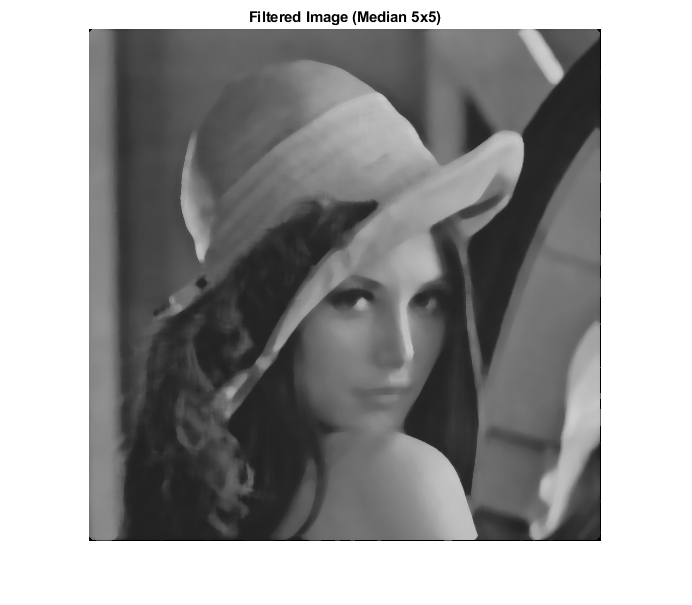


filtered_5x5 = medfilt2(noisy_lena, [5 5]);

figure;
imshow(filtered_5x5)
title('Filtered Image (Median 5x5)')


% The 5x5 filtered image seems to be more blurry than that of the 3x3
% filtered image. As the window size of the median filter increases, 
% the image gets increasingly blurry.

Functions

function my_gray = grayscale_intensity(rgb)
    R = rgb(:,:,1);
    G = rgb(:,:,2);
    B = rgb(:,:,3);
    
    my_gray = (0.3*R) + (0.6*G) + (0.1*B);
    
    my_gray = uint8(my_gray);
end